1번 문제

A = [ 1 4 2; 2 4 100; 7 9 7; 3 pi 42]; B = log10(A);
B(2,:)

ans =     0.3010    0.6021    2.0000


sum(B(2,:))

ans = 2.9031

C = (B(2,:)) .* A(:,1)

C =     0.3010    0.6021    2.0000
    0.6021    1.2041    4.0000
    2.1072    4.2144   14.0000
    0.9031    1.8062    6.0000


max(C)

ans =     2.1072    4.2144   14.0000


D = A(1,:) ./ B(1:3,3)'

D =     3.3219    2.0000    2.3666


sum(D)

ans = 7.6885

2번 문제

% 상수 설정
v0 = 50;            % 초기 속도 (m/s)
A_deg = 50;         % 발사각 (degree)
A_rad = deg2rad(A_deg); % MATLAB 삼각함수는 라디안을 사용하므로 변환
g = 9.81;           % 중력 가속도 (m/s^2)

% (a) 충돌 시간 t_hit과 최고 높이 y_max 구하기
t_hit = (2 * v0 * sin(A_rad)) / g;

% y_max: 수직 속도가 0이 되는 지점의 높이
% t_peak = t_hit / 2 일 때 발생
t_peak = t_hit / 2;
y_max = (v0 * sin(A_rad)) * t_peak - 0.5 * g * t_peak^2;

fprintf('(a) 충돌 시간 t_hit: %.4f s\n', t_hit);

(a) 충돌 시간 t_hit: 7.8088 s


fprintf('    최고 높이 y_max: %.4f m\n', y_max);

    최고 높이 y_max: 74.7737 m


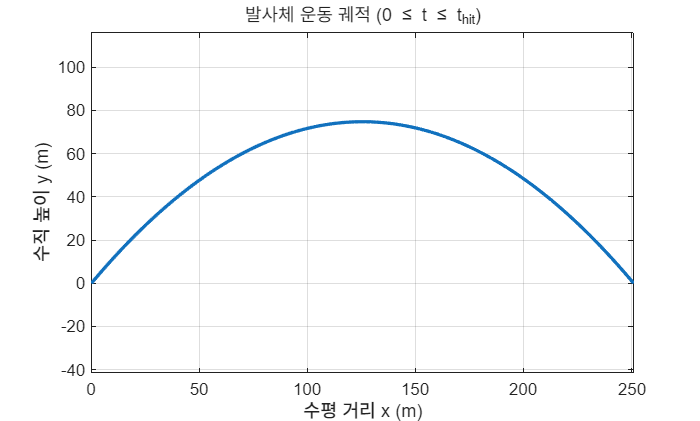


% (b) 0 <= t <= t_hit 구간에서 x 대 y 그래프 그리기
t_vec = linspace(0, t_hit, 100); % 0부터 t_hit까지 100개의 점 생성

x = (v0 * cos(A_rad)) * t_vec;
y = (v0 * sin(A_rad)) * t_vec - 0.5 * g * t_vec.^2;

figure; % 새로운 그래프 창 생성
plot(x, y, 'LineWidth', 2);
grid on;
xlabel('수평 거리 x (m)');
ylabel('수직 높이 y (m)');
title('발사체 운동 궤적 (0 \leq t \leq t_{hit})');
axis equal; % x축과 y축의 비율을 동일하게 설정

## 3번 함수 그래프

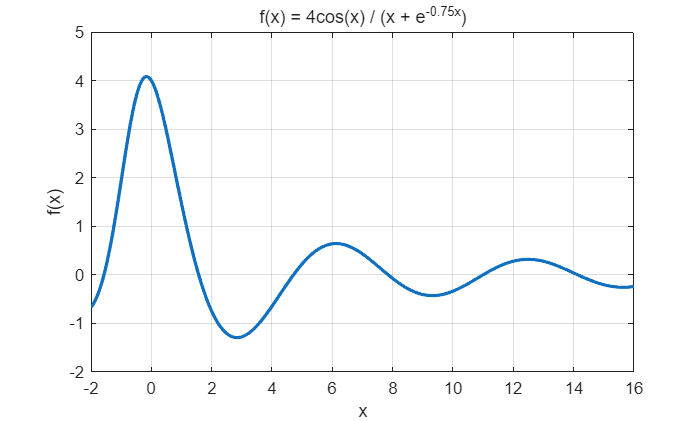


clc; clear;

% x범위 (부드러운 곡선을 위해 점 많이)
x = linspace(-2, 16, 1000);

%함수 정의
f = (4*cos(x)) ./(x + exp(-0.75*x));

%그래프 그리기
plot(x, f, 'LineWidth', 2);
grid on;

%그래프 꾸미기
xlabel('x');
ylabel('f(x)');
title('f(x) = 4cos(x) / (x + e^{-0.75x})');

4번 그래프 문제

% (a) 5x3 소비 행렬을 생성
% 각 행은 재료(1~5), 각 열은 월(5월, 6월, 7월)의 구매량을 나타낸다
C = [5, 4, 6;
     3, 2, 4;
     6, 5, 3;
     3, 5, 4;
     2, 4, 3];
disp('(a) 5x3 소비 행렬:');

(a) 5x3 소비 행렬:


disp(C);

     5     4     6
     3     2     4
     6     5     3
     3     5     4
     2     4     3




% (b) 각 달의 총 소비량을 구하자
% 행렬의 열 단위(각 월) 합계를 구함 (결과: 1x3 벡터)
monthly_total = sum(C, 1);
disp('(b) 각 달의 총 소비량 (5월, 6월, 7월 순):');

(b) 각 달의 총 소비량 (5월, 6월, 7월 순):


disp(monthly_total);

    19    20    20




% (c) 3개월 동안 각 재료별 총 소비량을 구하자
% 행렬의 행 단위(각 재료) 합계를 구함 (결과: 5x1 벡터)
material_total = sum(C, 2);
disp('(c) 각 재료별 총 소비량 (재료 1~5 순):');

(c) 각 재료별 총 소비량 (재료 1~5 순):


disp(material_total);

    15
     9
    14
    12
     9




% (d) 전체 기간 동안의 총 소비량을 구하기
% 행렬의 모든 요소의 합계를 구함
grand_total = sum(C, 'all'); % 하위 버전의 경우 sum(sum(C)) 사용
disp('(d) 전체 기간 동안의 총 소비량:');

(d) 전체 기간 동안의 총 소비량:


disp(grand_total);

    59



5번 문제

% 첫 번째 다항식
p1 = [5, 0, -3, 7, 10];
% 두 번째 다항식
p2 = [4, -7, 9, 2];

result_a = conv(p1, p2);

disp('(a) 다항식의 곱 결과 계수 (내림차순):');

(a) 다항식의 곱 결과 계수 (내림차순):


disp(result_a);

    20   -35    33    59   -36   -13   104    20





% 분자
num_b = [5, -7, 2, 8];
% 분모
den_b = [6, 3, -2];

[q, r] = deconv(num_b, den_b);

disp('(b) 다항식의 나눗셈 결과:');

(b) 다항식의 나눗셈 결과:


disp('몫 (q):');

몫 (q):


disp(q);

    0.8333   -1.5833



disp('나머지 (r):');

나머지 (r):


disp(r);

         0         0    8.4167    4.8333




% 분자
num_c = [36, -8, 0, 2];
% 분모
den_c = [36, -5, 4, -3];

x_val = 5;

% 분자와 분모 각각에 x = 5 대입 후 계산
val_num = polyval(num_c, x_val);
val_den = polyval(den_c, x_val);
result_c = val_num / val_den;

disp('(c) x = 5에서의 식의 값:');

(c) x = 5에서의 식의 값:


disp(result_c);

    0.9795



6번 문제

% (a) 위 표의 정보를 갖는 구조체 배열을 생성
% 구조체 배열 이름은 'bridges'로 정의
bridges(1).location = 'Smith St.';
bridges(1).max_load = 80;
bridges(1).year_built = 1928;
bridges(1).maintenance_year = 2025;

bridges(2).location = 'Hope Ave.';
bridges(2).max_load = 90;
bridges(2).year_built = 1950;
bridges(2).maintenance_year = 2027;

bridges(3).location = 'Clark St.';
bridges(3).max_load = 85;
bridges(3).year_built = 1933;
bridges(3).maintenance_year = 2024;

bridges(4).location = 'North Rd.';
bridges(4).max_load = 100;
bridges(4).year_built = 1960;
bridges(4).maintenance_year = 2023;

disp('(a) 생성된 구조체 배열:');

(a) 생성된 구조체 배열:


disp(bridges);

  다음 필드를 포함한 1×4 struct 배열:

    location
    max_load
    year_built
    maintenance_year




% (b) Clark St. 다리의 유지기한을 2024년에서 2026년으로 수정
% Clark St.은 배열의 3번째 요소
bridges(3).maintenance_year = 2026;

disp('(b) Clark St. 유지기한 수정 완료.');

(b) Clark St. 유지기한 수정 완료.



% (c) 다음 다리 정보를 구조체 배열에 추가
% (Shore Rd., 85, 1997, 2022)
new_index = length(bridges) + 1; % 현재 배열 길이에 1을 더해 다음 인덱스 지정
bridges(new_index).location = 'Shore Rd.';
bridges(new_index).max_load = 85;
bridges(new_index).year_built = 1997;
bridges(new_index).maintenance_year = 2022;

disp('(c) 새로운 다리 정보 추가 완료:');

(c) 새로운 다리 정보 추가 완료:


disp(bridges(new_index));

            location: 'Shore Rd.'
            max_load: 85
          year_built: 1997
    maintenance_year: 2022

